# MARTEC Subsampling

Selects a subset of data points from the MARTEC registry where sampling rate is consistent and evaluates correlation to clinical reports based on the maximum viral load found weekly in each campus

## Imports MARTEC registries

opts = delimitedTextImportOptions("NumVariables", 9);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Semana", "Campus", "Ncampus", "Edificio", "Sitio", "Estado", "NEstado", "Copias_L", "CasosSem"];
opts.VariableTypes = ["double", "categorical", "double", "double", "categorical", "categorical", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Campus", "Sitio", "Estado"], "EmptyFieldRule", "auto");

% Import the data
MARTEC_Casos = readtable("/MATLAB Drive/Analisis de datos MARTEC/MARTEC_Casos.csv", opts)

MARTEC_Casos = 9664x9 table
    Semana        Campus        Ncampus    Edificio          Sitio               Estado        NEstado     Copias_L     CasosSem
    ______    ______________    _______    ________    __________________    ______________    _______    __________    ________

       5      Aguascalientes       1          6        LIFE                  AGUASCALIENTES       1                0     116.29 
       7      Aguascalientes       1          6        LIFE                  AGUASCALIENTES       1       1.3408e+05     68.571 
       8      Aguascalientes       1          1        Colector principal    AGUASCALIENTES       1       1.4648e+06     62.286 
       9      Aguasc

clear opts

Ed_totales=343; %Total buildings in the study

## Obtains the total number of samples taken across all campuses in each week

NSamples=[];
for i=min(MARTEC_Casos.Semana):1:max(MARTEC_Casos.Semana)
    MARTEC_Sem=MARTEC_Casos(MARTEC_Casos.Semana==i,:);
    if height(MARTEC_Sem)>0
        Rat_Sample=height(MARTEC_Sem)/Ed_totales;
        NSamples=[NSamples; i height(MARTEC_Sem) Rat_Sample];
    else
        NSamples=[NSamples; i 0 0];
    end
end
NSamples

NSamples =     5.0000    1.0000    0.0029
    6.0000    7.0000    0.0204
    7.0000   21.0000    0.0612
    8.0000   54.0000    0.1574
    9.0000   62.0000    0.1808
   10.0000   48.0000    0.1399
   11.0000   51.0000    0.1487
   12.0000   59.0000    0.1720
   13.0000   54.0000    0.1574
   14.0000   22.0000    0.0641


## Presents the number of samples in each week as a bar plot

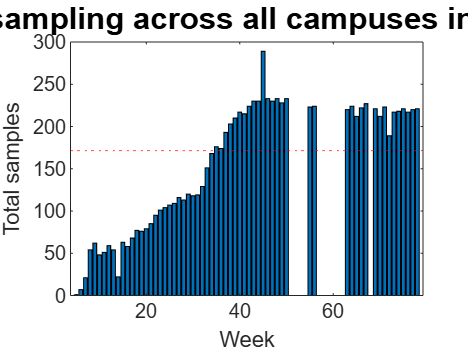

Min_Cov=0.50; %Threshold for selection, expressed as a rate of total buildings
bar(NSamples(:,1),NSamples(:,2))
xlabel("Week")
ylabel("Total samples")
title("Weekly sampling across all campuses in the study","FontSize",15)
yline(Min_Cov*Ed_totales,"LineStyle",":","Color",'r')

Sem=NSamples(NSamples(:,3)>=Min_Cov,1); %Weeks selected for subsample
NSem=height(Sem) %Total weeks selected for subsample

NSem = 33

Rat_Sem=NSem/height(NSamples)*100 %Ratio of weeks selected for subsample

Rat_Sem = 44.5946

## Obtains the subsample based on the selected threshold

Subsample=ismember(MARTEC_Casos.Semana,Sem);
Sub_MARTEC=MARTEC_Casos(Subsample,:);

## Calculates the correlation between the weekly maximum viral load found in each campus and the clinical reports in the selected subsample

Max_Sub=[];
Corr_Sub=[];
for i=1:1:max(Sub_MARTEC.Ncampus)
    Sub_Campus=Sub_MARTEC(Sub_MARTEC.Ncampus==i,:);
    if height(Sub_Campus)>0
        for j=min(Sub_Campus.Semana):1:max(Sub_Campus.Semana)
            Sub_Sem_Campus=Sub_Campus(Sub_Campus.Semana==j,:);
            if height(Sub_Sem_Campus)>0
                [~,maxidx]=max(Sub_Sem_Campus.Copias_L);
                Max_Sub_Sem_Campus=Sub_Sem_Campus(maxidx,:);
                Max_Sub=[Max_Sub;Max_Sub_Sem_Campus];
            end
        end
        [Corr_Sub_Campus,psub_camp]=corr(Max_Sub.Copias_L,Max_Sub.CasosSem,"Type","Pearson");
        Corr_Sub=[Corr_Sub; i height(Max_Sub) nnz(Max_Sub.Copias_L) Corr_Sub_Campus psub_camp];
        Max_Sub=[];
    end
end
Corr_Sub=array2table(Corr_Sub,"VariableNames",["NCampus","Weekly samplings","Detection weeks","Correlation","p-value"])

Corr_Sub = 38x5 table
    NCampus    Weekly samplings    Detection weeks    Correlation     p-value  
    _______    ________________    _______________    ___________    __________

       1              33                 15               0.2549        0.15226
       2              32                 10             0.032332        0.86055
       3              33                 22              0.65113     4.0691e-05
       4              33                  6              0.86623      7.399e-11
       5              31                  9              0.77203     3.6511e-07
       6              33                 12              0.76617     2.0262e-07
       7              32                  5              0.72131     3.1952e-06
       8              31                  7              0.72562     3.8573e-06
       

Nom_Campus=unique(MARTEC_Casos.Campus);
Nom_Campus(Nom_Campus=="Veracruz")=[]; %Eliminates Veracruz because of insuficient sampling
Corr_Sub.Campus=Nom_Campus;
Corr_Sub=movevars(Corr_Sub,"Campus","Before","NCampus")

Corr_Sub = 38x6 table
           Campus            NCampus    Weekly samplings    Detection weeks    Correlation     p-value  
    _____________________    _______    ________________    _______________    ___________    __________

    Aguascalientes              1              33                 15               0.2549        0.15226
    CDJ                         2              32                 10             0.032332        0.86055
    CDMX                        3              33                 22              0.65113     4.0691e-05
    Celaya                      4              33                  6              0.86623      7.399e-11
    Chiapas                     5              31                  9              0.77203     3.6511e-07
    Chihuahua                   6     

nnz(Corr_Sub.("p-value")<0.05) %Number of campuses were correlations were statistically significant

ans = 27